Number of x data points: 

n = 100;

Degree of fit polynomial:

m = 3;

List of coefficients. This also determines degree of generated polynomial:

coeffs =  [1.5 -2.5 0.7 -1.2];

Experimental rms value:

e = 10;

Generate the data and plot it:

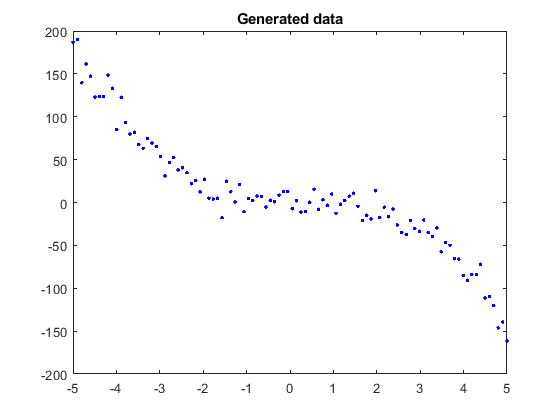

generated_data = poly_data_gen(n,coeffs,e);

plot(generated_data(:, 1), generated_data(:, 2), "b.")
hold on
title("Generated data")
hold off

Fit curve using polynomial curve fitting:

fit_coeffs = poly_least_squares(m, generated_data) %calculate fit coefficients

fit_coeffs =     1.9649
   -2.4356
    0.7901
   -1.2500



%in case we want to use the linear fit function from earlier:

%[a,b] = least_squares(generated_data(:, 1), generated_data(:, 2));
%fit_coeffs = [a,b]


%generate fitted curve y values
xvals = linspace(-5,5,n).';
yvals = zeros(n, 1); %y value array to fill
for i = 1:length(fit_coeffs)
	yvals = yvals+fit_coeffs(i).*xvals.^(i-1);
end

Plot fitted curve on top of generated data

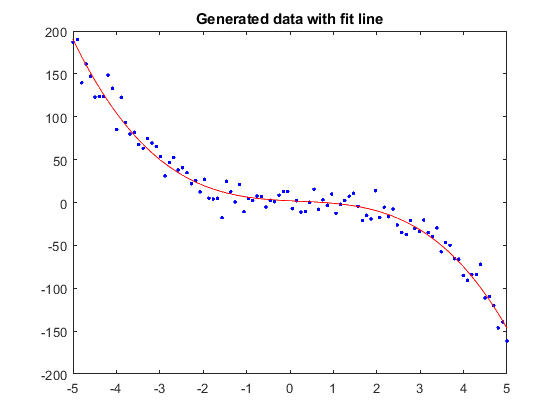

plot(generated_data(:, 1), generated_data(:, 2), "b.") %generated data
hold on
plot(xvals, yvals, "r-") %fitted data
title("Generated data with fit line")